# eVTOL Powertrain ECU HIL Testing

## Description

This reference example demonstrates system-level and component-level hardware-in-the-loop (HIL) testing for powertrain ECUs of a fully-electric vertical take-off and landing aircraft (eVTOL). The eVTOL powertrain includes a 400V lithium battery pack, implemented using Simscape™ Battery™, and four 200kW propulsion motor drives modeled as permanent magnet synchronous motors (PMSMs) with two-level three-phase inverters. In addition to the powertrain, the eVTOL plant model also includes a flight controller and flight dynamics.

HIL simulation of the powertrain components is powered by FPGA-based motor drive simulation, featuring encoder and current sensing emulation, as well as realistic battery cell-level emulation for 24 of the 100 cells in the eVTOL battery pack. The aircraft and environment can be visualized in a photorealistic 3D environment powered by Unreal Engine® from Epic Games.

The provided HIL setup enables testing of the following powertrain ECUs:

- The motor control unit (MCU) governing one of the 200kW electric drives

- The battery management system (BMS), which includes a battery management unit (BMU) and two cell monitoring units (CMUs).

## Learn How-To:

- Model a 400V battery system using Simscape™ Battery™.

- Interface the battery model with battery cell emulation hardware.

- Simulate eVTOL propulsion motor drives, capturing current ripples and switching harmonics.

- Implement bus and signal-level communication with real ECUs.

- Perform HIL testing at both system and component levels.

- Accelerate testing with automated and continuous integration workflows.

- Visualize the aircraft and environment in a photorealistic 3D environment.

## **Supported Model-based Design Use Cases **

This example supports the following simulation modes (see image below):

Battery System:

- Desktop and Real-time Model-in-the-Loop: Both the battery plant and BMS controller can run on the development computer for Desktop MIL or in real-time on the Speedgoat HIL test system to validate real-time aspects. The development computer is used to control the simulation, fine-tune battery plant and BMS controller parameters, and measure/record real-time data.

- Hardware-in-the-Loop: Reuse existing controller model to generate code onto general purpose automotive microcontroller, acting as Battery Management Unit (BMU). Extend the BMU with a Cell Monitoring Unit (CMU) and the HIL testbench with battery cell emulation hardware. Validate BMS functions by interfacing the BMS (BMU + CMU) controller against the battery digital twin running on Speedgoat hardware. Conduct both interactive and automated HIL testing.

Motor Drive:

- Desktop Model-in-the-Loop: Both the PMSM drive plant and motor controller run on the development computer. The PMSM drive is modeled using an average inverter, which uses PWM duty-cycle and DC voltage input and the phase voltages as output. This plant model is hereafter referred to as average model. Use this simulation mode to test and verify the FOC controls against the electric drive in closed-loop desktop simulation.

- Real-time Model-in-the-Loop: Both the PMSM drive plant and motor controller run in real-time on a Speedgoat HIL test system. The PMSM with switching inverter executes on a [Simulink®-Programmable FPGA I/O](https://www.speedgoat.com/products-services/i-o-connectivity/simulink-programmable-fpga-i-o). The switching inverter is controlled by firing pulses produced by a PWM generator. This plant version provides the required resolution and fidelity for simulating high frequency switching dynamics such as current ripple and spatial harmonics. Use this mode to validate real-time aspects of both plant and controller. The development computer is used to control the real-time simulation, fine-tune PMSM drive and FOC parameters, and measure real-time signals including ripples and switching harmonics directly on Simulink.

- Hardware-in-the-Loop: Interface FOC controller running on intended target hardware with the PMSM drive detailed model running on the Speedgoat HIL test system. Use this mode to perform interactive and automated HIL testing of your embedded controller.

                            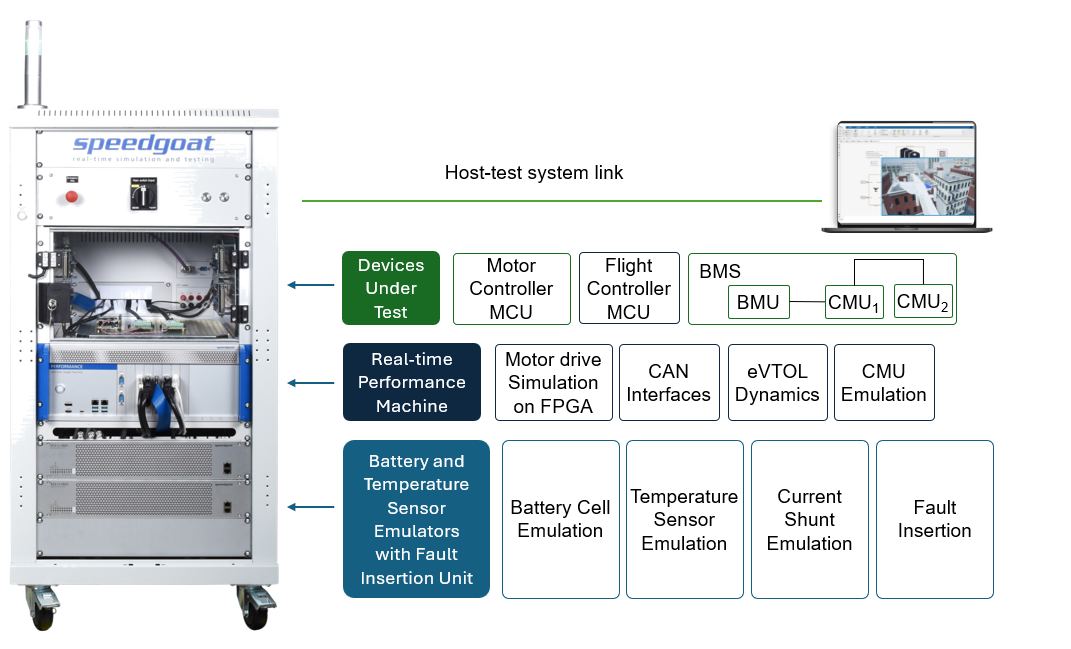

## System Requirements

###     MathWorks® **Products**

- [Simulink® Real-Time™](https://ch.mathworks.com/products/simulink-real-time.html?s_tid=srchtitle)

- [UAV Toolbox](https://ch.mathworks.com/products/uav.html)

- [Simscape™ Battery™](https://ch.mathworks.com/products/simscape-battery.html)

- [Motor Control Blockset™](https://ch.mathworks.com/products/motor-control.html)

- [Embedded Coder®](https://ch.mathworks.com/products/embedded-coder.html)

- [C2000™ Microcontroller Blockset](https://ch.mathworks.com/products/ti-c2000-microcontroller.html)

- [Simulink Test™](https://ch.mathworks.com/products/simulink-test.html)

###    ** Speedgoat Products**

- [Performance Real-Time Target Machine](https://www.speedgoat.com/products-services/real-time-target-machines/performance-real-time-target-machine)                        

- [IO611 CAN FD I/O Module](https://www.speedgoat.com/products/communication-protocols-can-fd-io611)

- [Battery Cell Emulator](https://www.speedgoat.com/products/battery-management-systems-battery-cell-emulator)

- [IO334: Programmable FPGA I/O module with Xilinx Kintex 7 + Analog I/O for Simulink ](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io334)

- [IO3XX-21: Digital TTL pulse/encoder/SPI/I2C I/O support for Simulink](https://www.speedgoat.com/products/simulink-programmable-fpgas-fpga-i-o-modules-io3xx-21)

- [HDL Coder Integration Package](https://www.speedgoat.com/help/hdlcoder/page/index)

- [Motion Control HDL I/O Blockset](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/index)

- [I/O Module supporting CAN (Controller Area Network)](https://www.speedgoat.com/products-services/communications-protocols/can)

- [Launchpad Development Kit](https://www.speedgoat.com/products/launchpad-development-kit)

###     Third-Party Products

- [NXP Evaluation Board for Automotive General Purpose (S32K144-Q100)](https://www.nxp.com/design/development-boards/automotive-development-platforms/s32k-mcu-platforms/s32k144-q100-evaluation-board-for-automotive-general-purpose:S32K144EVB)

- [NPX Isolated Network High-Speed Transceiver (MC33664ATL)](https://www.nxp.com/design/software/analog-expert-software-and-tools/sdk-analog-expert-drivers/evaluation-board-for-mc33664atl-isolated-network-high-speed-transceiver:FRDMDUAL33664EVB?van=tidFRDMDUAL33664EVB)

- [NXP Cell Monitoring Unit (MC33771)](https://www.nxp.com/products/power-management/battery-management/battery-cell-controllers/evaluation-board-for-mc33771-with-isolated-daisy-chain-communication:FRDM33771BTPLEVB)

- [NXP Support Package S32K1xx](https://ch.mathworks.com/matlabcentral/fileexchange/64740-nxp-support-package-s32k1xx)

- [Unreal Engine® from Epic Games®](https://www.unrealengine.com/en-US)

## eVTOL Plant Components

For more details on modeling and simulating the various eVTOL plant components, refer to the following resources:

- Flight dynamics and flight Controller: [Design and Tune Controller for VTOL UAV](https://mathworks.com/help/uav/ug/design-tune-controller-vtol-uav.html)

- Photorealistic 3D simulation: [Visualize VTOL UAV Mission Over Urban Environment](https://ch.mathworks.com/help/uav/ug/visualize-vtol-flight-mission-over-urban-environment.html)

- FPGA-based motor drive modeling and simulation: [Three-Phase PMSM with Two-Level Inverter](https://www.speedgoat.com/help/hdlcoder/page/sg_help_motioncontrol/examples/PMSM3P2LInverterCHIL)

Component-level HIL testing for BMS and MCU controllers is covered in the following Speedgoat reference examples:

- [Hardware-in-the-Loop Testing of Battery Management Systems](https://www.speedgoat.com/knowledge-center/reference-examples/reference-example-hardware-in-the-loop-testing-of-battery-management-systems)

- [Controller HIL Testing for Three-Phase PMSM with Two-Level Inverter](https://www.speedgoat.com/knowledge-center/reference-examples/demo-controller-hil-testing-for-three-phase-pmsm-with-two-level-inverter)

## HIL Testbench Configuration 

### Generate and Deploy BMS Code

This section instructs how to generate code and run the BMS controller logic on the [NXP Evaluation Board for Automotive General Purpose (S32K144-Q100)](https://www.nxp.com/design/development-boards/automotive-development-platforms/s32k-mcu-platforms/s32k144-q100-evaluation-board-for-automotive-general-purpose:S32K144EVB).

% Open model containing controller logic for F28379D target hardware
mdl1 = 'Controller_HIL.slx';
open_system(mdl1);

% Connect target hardware to host computer (USB)

% Build and Deploy Code to target hardware
slbuild(mdl1);

### Connect BMS to the HIL Test System 

BMS Controller (consisting of a BMU and two CMUs) and the Speedgoat HIL test system should be connected according to the pin mapping outlined in the table below.

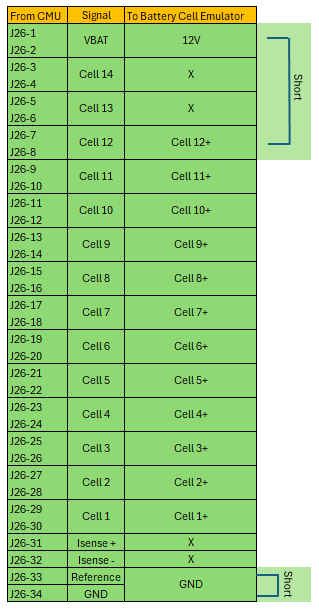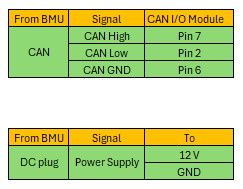

It is important to short-circuit VBAT and Cell 12 as the NXP Cell Monitoring Unit contains 14 cells and we only use 12 cells in one CMU each for this reference example. 'Reference' and 'GND' should also be shorted internally. The pins marked with 'X' can be left disconnected.

Connect the Cell monitoring Units as shown in the picture below.

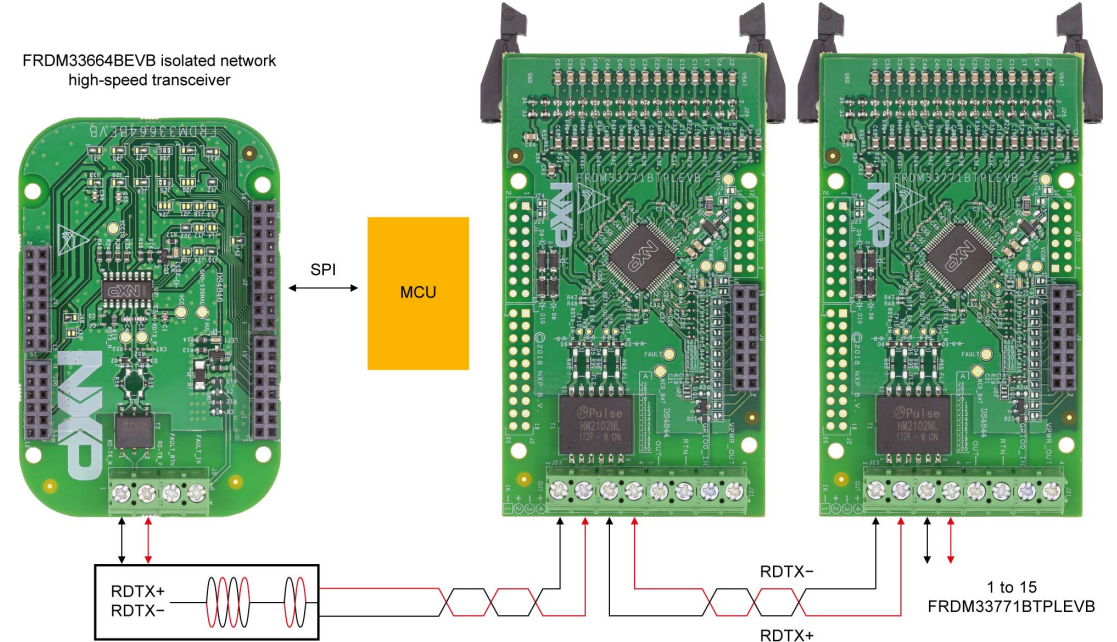

### Generate Battery Module

run BuildPack300V.m
run BuildPack96V.m

The above command will generate two battery module with 100 parallel assemblies with 1 cell each. One of the modules with 24 cells is used for emulating the battery while the other module with 76 cells is simulated in this reference example. Both modules are generated with a configuration to balance each parallel assembly externally. More information on how to generate battery packs using Simscape™ Battery™ can be found [here](https://ch.mathworks.com/help/simscape-battery/create-battery-pack.html).

### Generate and Deploy MCU Code

This section instructs how to generate code and run the FOC algorithm on the F28379D LaunchPad™ development kit for C2000™ Delfino™ MCU by Texas Instruments.

% Open model containing controller logic for F28379D target hardware
mdl = 'F28379DFirmware';
open_system(mdl);

% Connect target hardware to host computer (USB)

% Build and Deploy Code to target hardware
slbuild(mdl);

### Connect MCU to the HIL Test System

This reference example is specifically designed to run with the [Launchpad Development Kit](https://www.speedgoat.com/products/launchpad-development-kit) which greatly simplifies the interface between the test system's I/O modules and the controller. To set it up, simply connect the 98-Pin Analog cable from the IO334, the 68 pin Digital cable from the IO3xx-21 I/O interface extension and the D-sub 9 cable from the port 1 of the IO611 (the bottom port). Finally, ensure the jumper configuration matches the picture below, and connect the F28379D LaunchPad™ to a power supply using the Mini-USB cable (e.g. from the development computer or the USB-A port of the target machine).

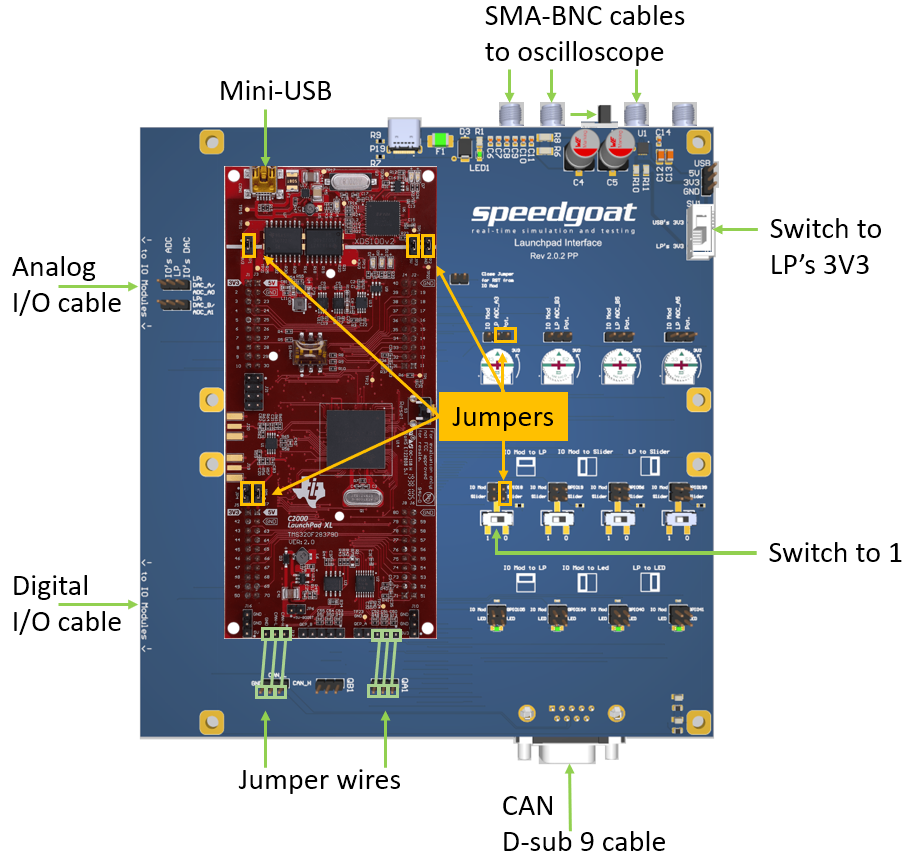

Alternatively, you can use a terminal board and the I/O box to manually wire the I/O modules to the controller.

The following table provides a detailed pin mapping between the F28379D LaunchPad™,  Speedgoat IO334 Simulink-Programmable FPGA I/O Module and Speedgoat CAN I/O Module.

First the IO3xx-21 expansion card should be connected to a terminal board according to the following connection between the terminal board and the F28379D LaunchPad™:

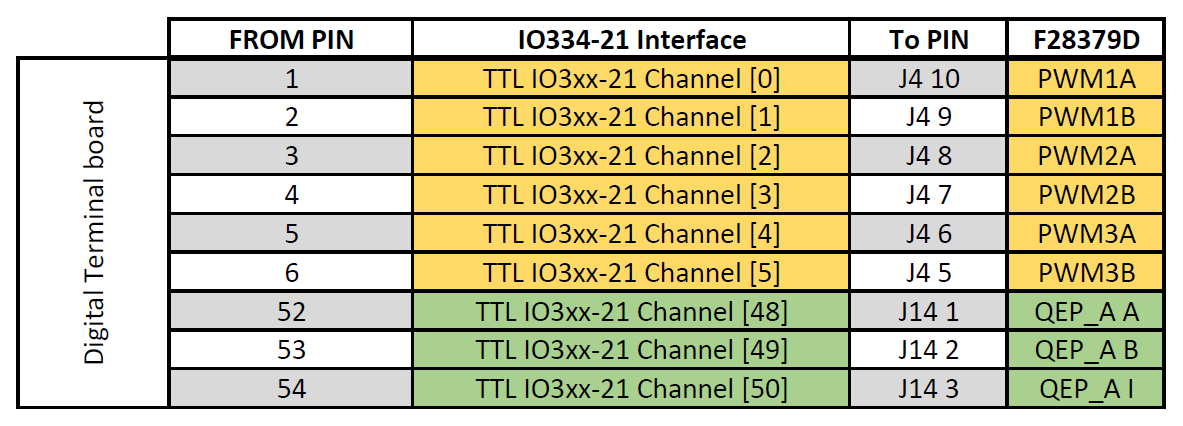

Then make the following connection using the IO334 I/O Box :

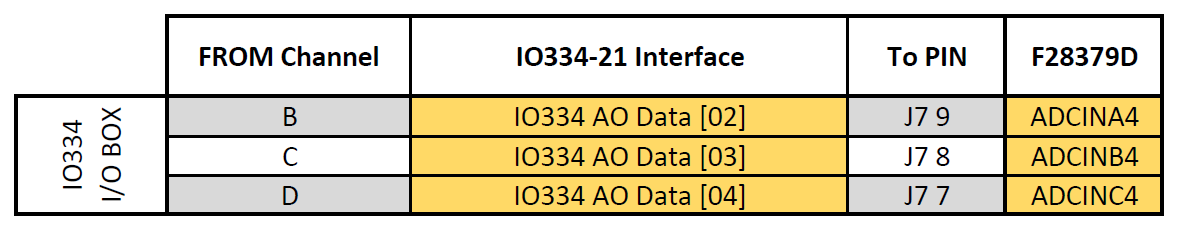

Finally, connect the Speedgoat IO611 CAN port to the F28379D LaunchPad™ pins.

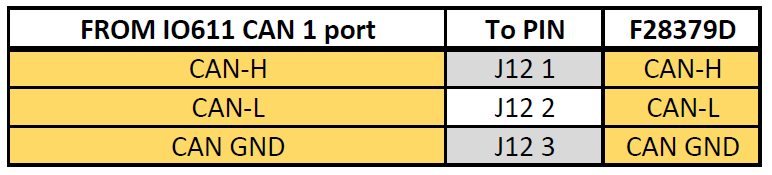

### Run eVTOL Model on HIL Test System

Following the configuration of the BMS and MCU controller hardware, it is time to build and run the eVTOL plant model in the HIL test system. 

% Open main system model
mdl1 = 'eVTOL_System';
open_system(mdl1);

% Open model with 3D visuals
mdl2 = 'eVTOL_3DVisuals';
open_system(mdl2);

% Configure testbench for HIL simulation using detailed model
switchBatteryConfig("HIL");
switchMotorConfig("HIL");

% Select guidance test scenario
run setupHoverGuidanceMission.m

% Build the Simulink model
slbuild(mdl1);

% Assign Realtime object to a variable
tg = slrealtime;

% Download and install the real-time application on the target machine
tg.load(mdl1);

% Start simulation of real-time application
tg.start;

% Open System User Interface subsystem

## Exercises

### **A. Monitor eVTOL System Data**

Using the System User Interface, you can monitor the rotor speed of all motors, battery state of charge (SOC), battery power consumption, and the current and voltage of the pack. Additionally, you can track the motor current dynamics for the motor simulated on the FPGA. If manual mode is activated, you can take direct control of the aircraft.

In the image below, a guided scenario is running the aircraft at a constant speed of 550 RPM, drawing 88kW of power from a 420V battery pack.

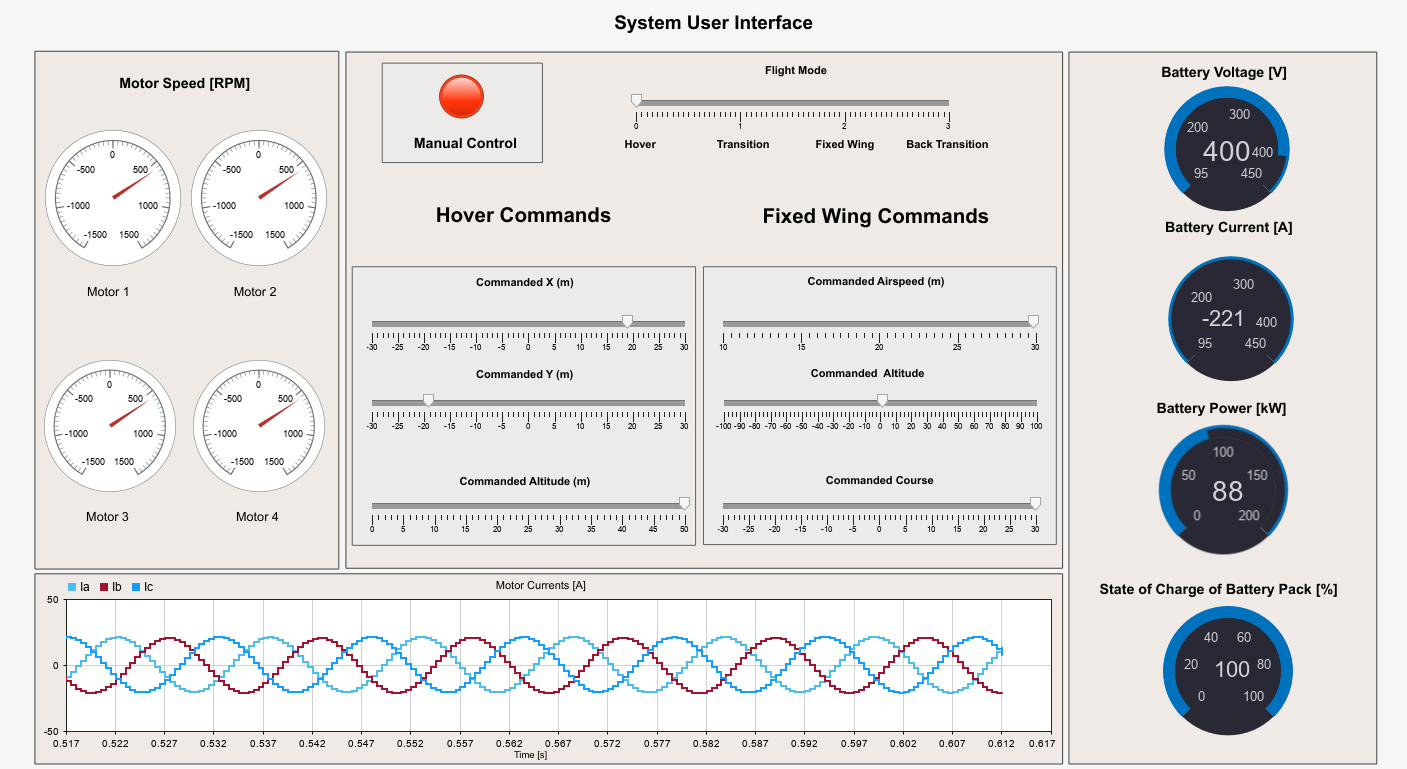

Aircraft maneuver visualization can be done using MATLAB’s native plotting capabilities or in a photorealistic 3D environment powered by Unreal Engine.

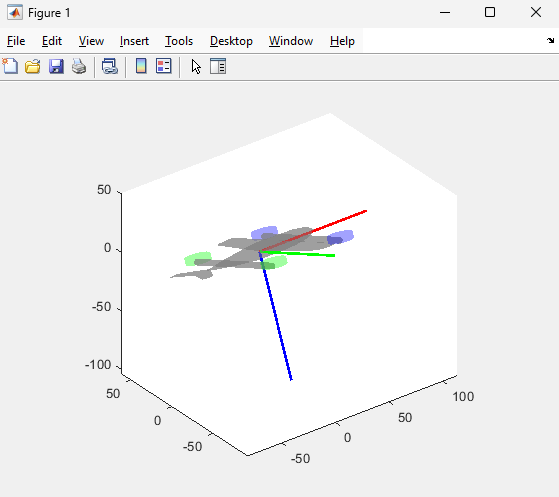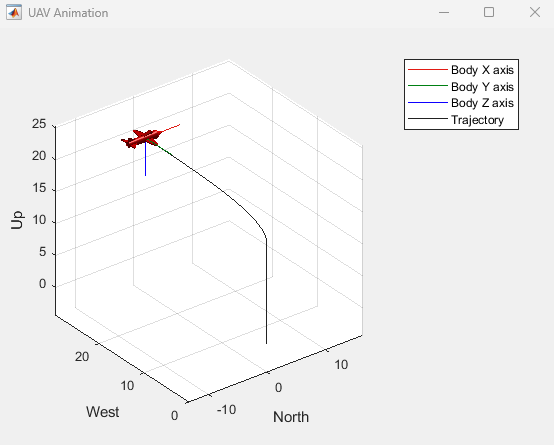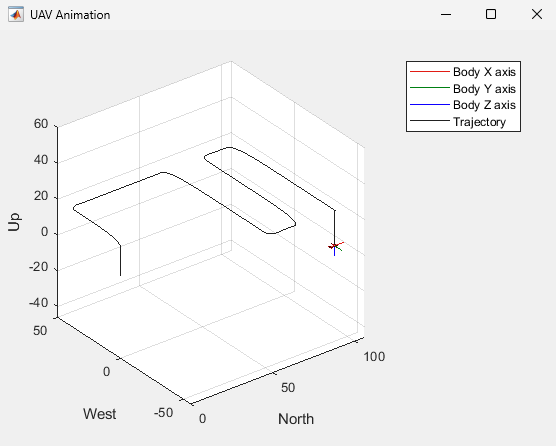

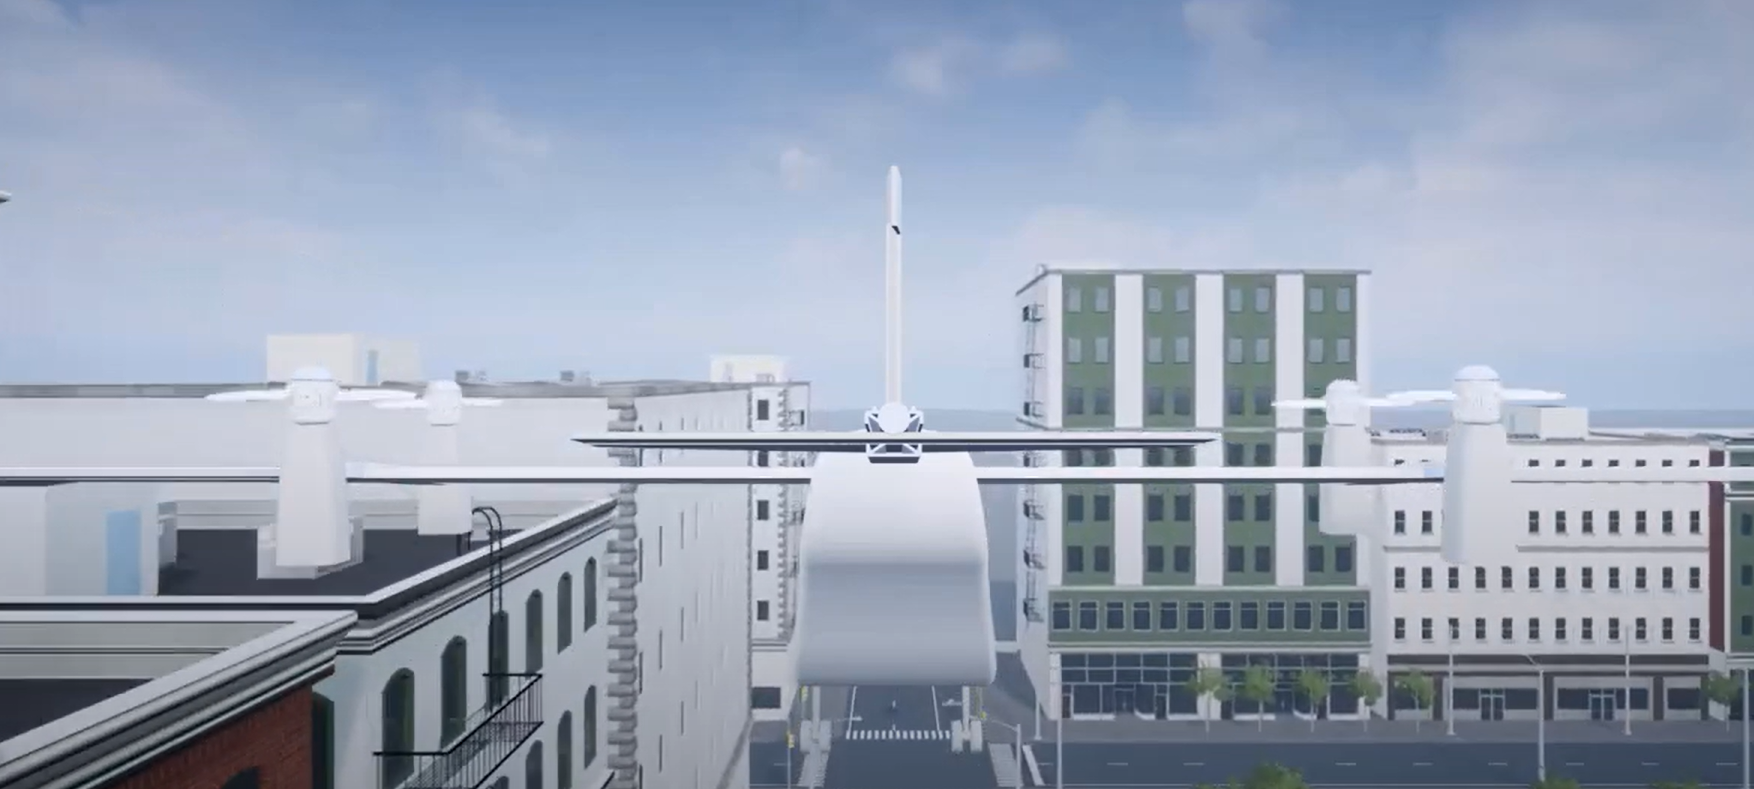

### B. BMS Interactive Testing

The BMS can be tested and validated using the BMS User Interface, which allows you to override cell parameters, introduce system faults, and monitor battery behavior. For example, you can test cell balancing functions and evaluate the controller’s response to faults.

In the image below, the battery pack is discharging to power four 200kW rotors with no load. The battery voltage is 397V, with a discharge current of 230A.

To validate the BMS passive cell balancing function, follow these steps:

- Override cell 12's voltage to 2.5V. This reduces cell 12's voltage and activates cell balancing for the other cells. You can see cell 12’s voltage at 2.5V in the "Observe Cell Parameters" section.

- The graph will show a balancing current of around 200mA for the other cells. You can enter any cell number (1 to 100) to view its specific balancing current.

- Similarly, you can override the voltage or temperature of any cell by entering its number.

- In the "Insert Faults" section, you can add short-circuit or broken-wire faults by selecting a cell number. Once a fault is added, the "Fault detected by BMS" alarm will appear in the lower-left section.

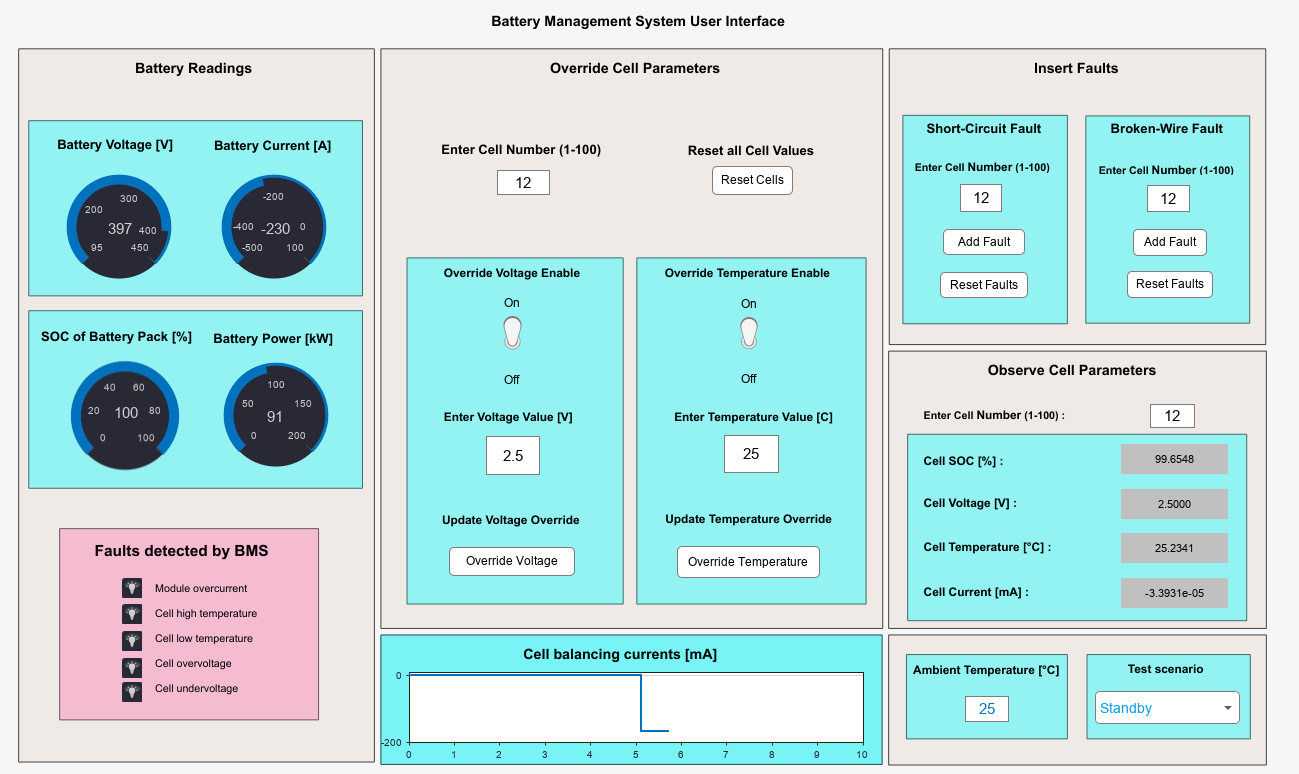

In the image below, you can see the parameters for cell 10, which is being balanced with a discharge current of 166mA. Additionally, the "Faults detected by BMS" section shows an under-voltage fault has been triggered for one of the cells.

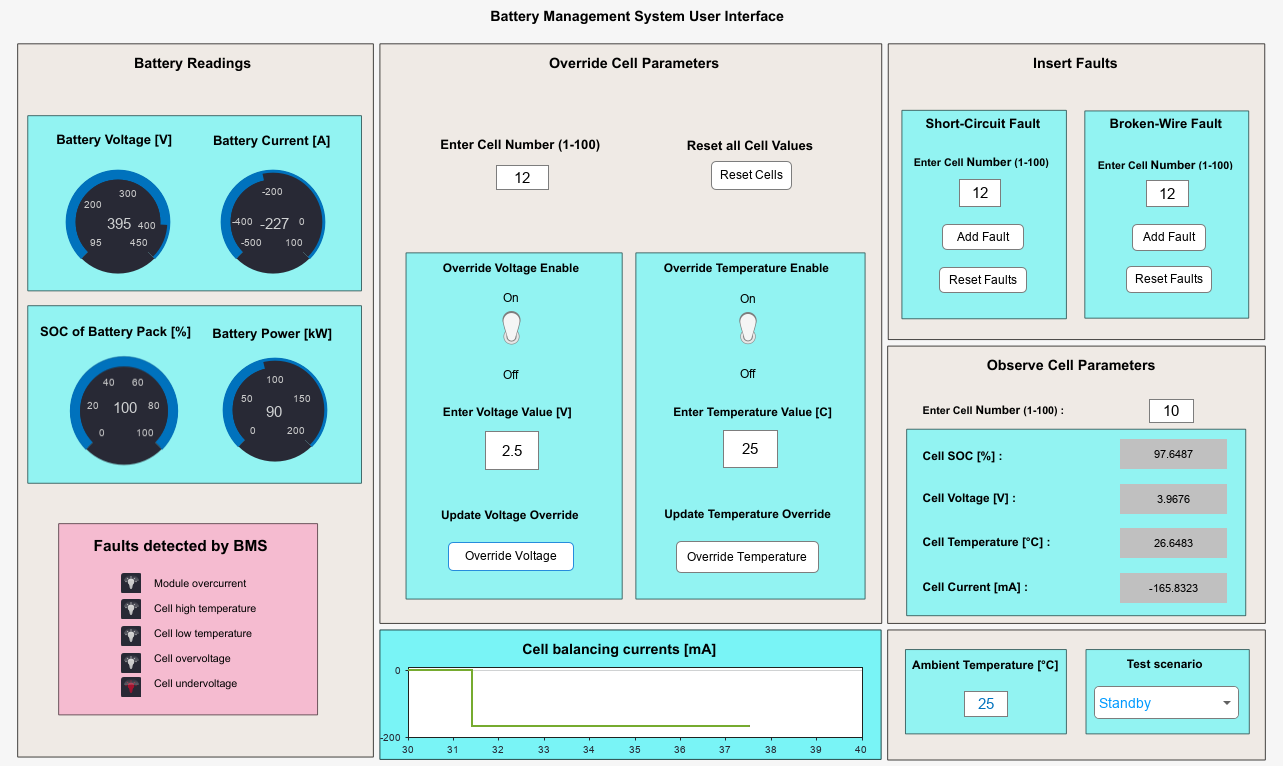

### C. MCU Interactive Testing

Note about motor drives: The eVTOL model includes four 200kW motors for the aircraft, with one motor simulated in an FPGA module using a high-fidelity inverter and encoder.

The Motor Drive User Interface allows users to interact with motor parameters, including tuning the motor controller gains and adding faults to the inverter. Key variables such as motor speed, encoder position, and motor currents can be monitored to fine-tune the controller. Motor commands are generated by the flight controller.

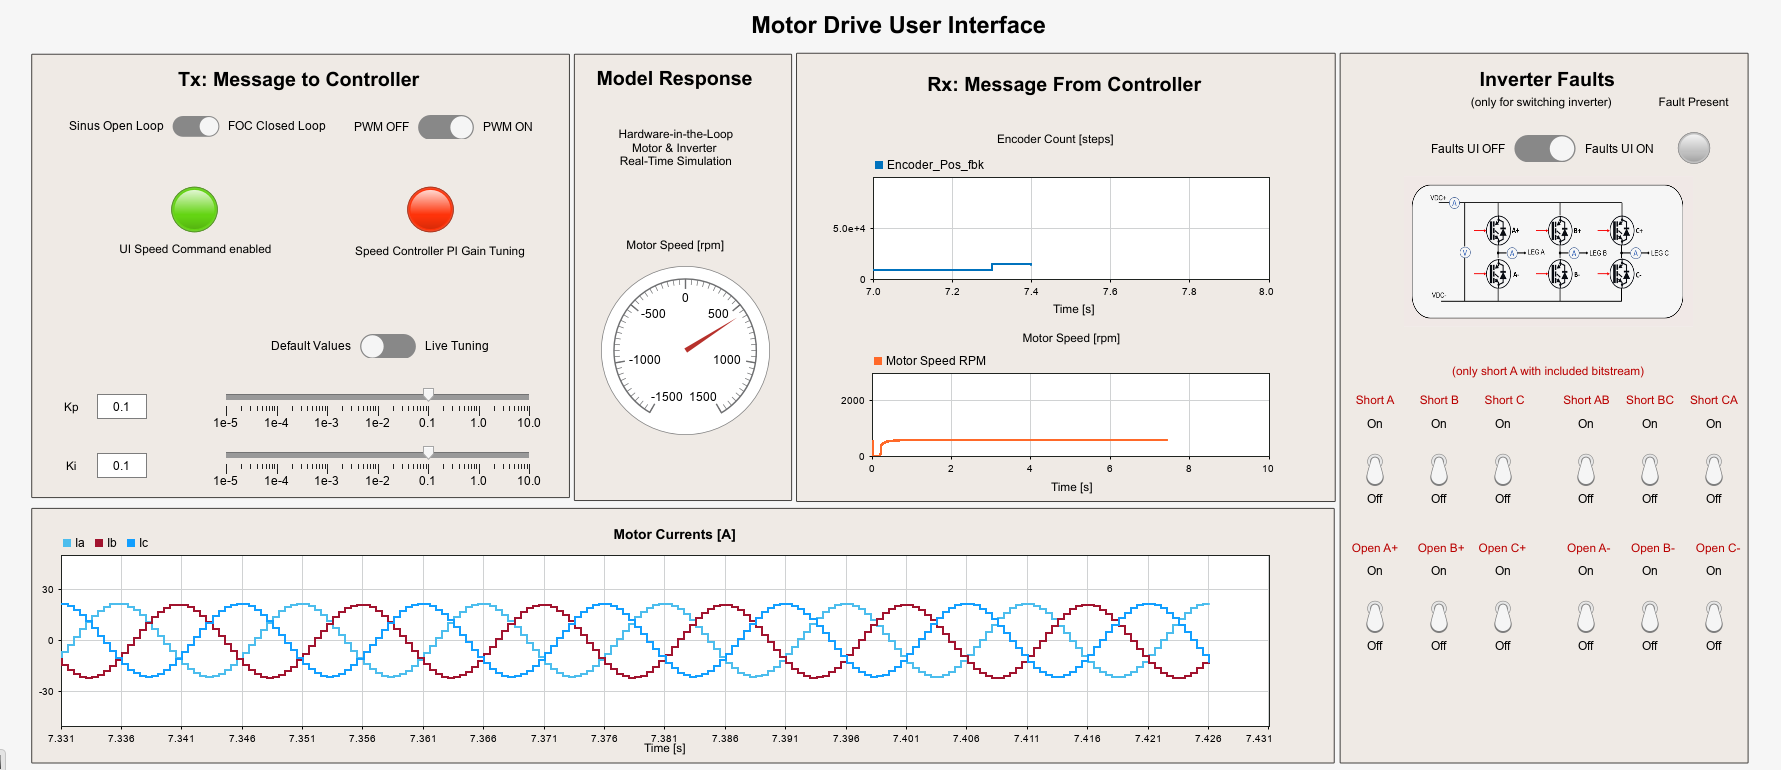

### D. Automate Testing

The following exercises demonstrate how to further automate system- and component-level HIL testing using [Simulink® Test™](https://ch.mathworks.com/products/simulink-test.html) and Continuous Integration (CI) workflows.

#### D1. System-Level Tests 

This example shows how to create a simple test that compares test results to a baseline data. Baseline tests are useful for regression testing when you change a model and want to ensure the output matches the baseline data.

Use the following commands to open Simulink® Test™ Manager with a predefined HIL baseline test scenario.

sltestmgr
sltest.testmanager.load('eVTOL_System_Test.mldatx')
sltest.testmanager.run

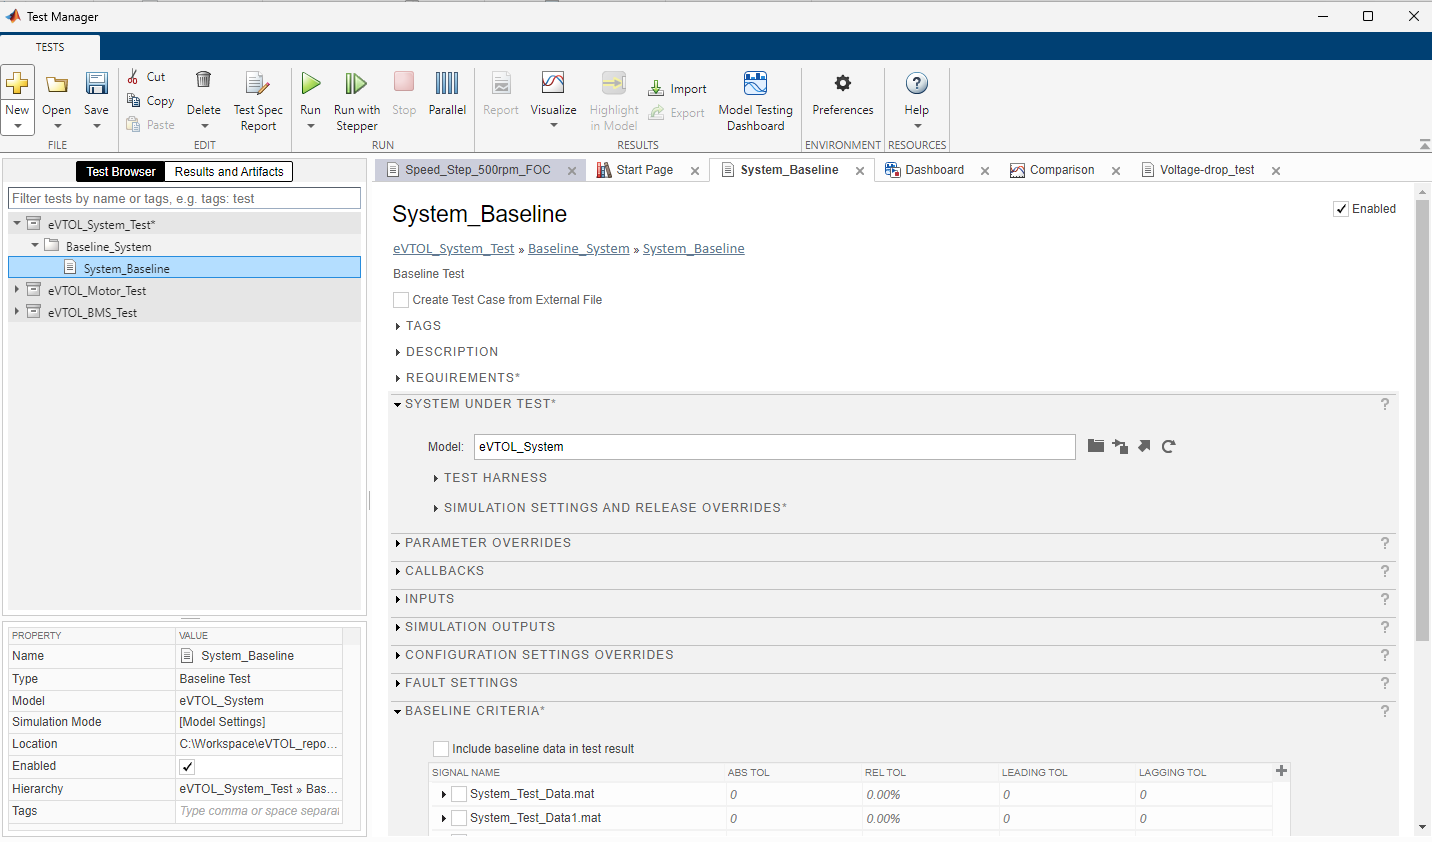

During the test run, the model gets compiled, deployed, and runs on the target machine. 

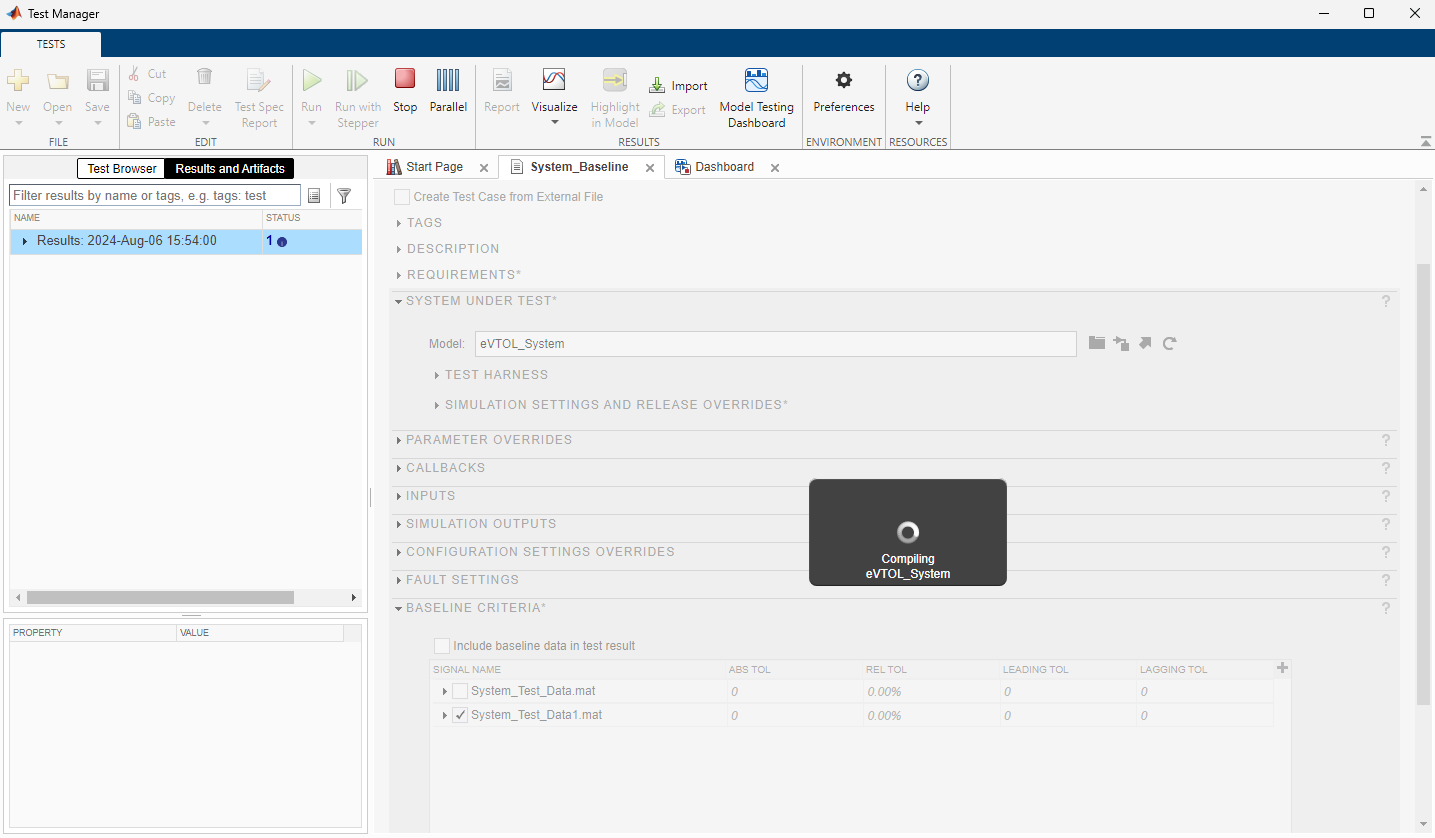

Once the test is complete, the results can be viewed in Simulink® Test™ Manager. In the Results and Artifacts pane, expand the results and select any signal under Baseline Criteria Result. The upper plot displays both the baseline and new HIL simulation output data, while the lower plot shows the difference between the two data sets. As seen, the speed feedback from the simulated motor matches the baseline with no errors, confirming the test has passed.

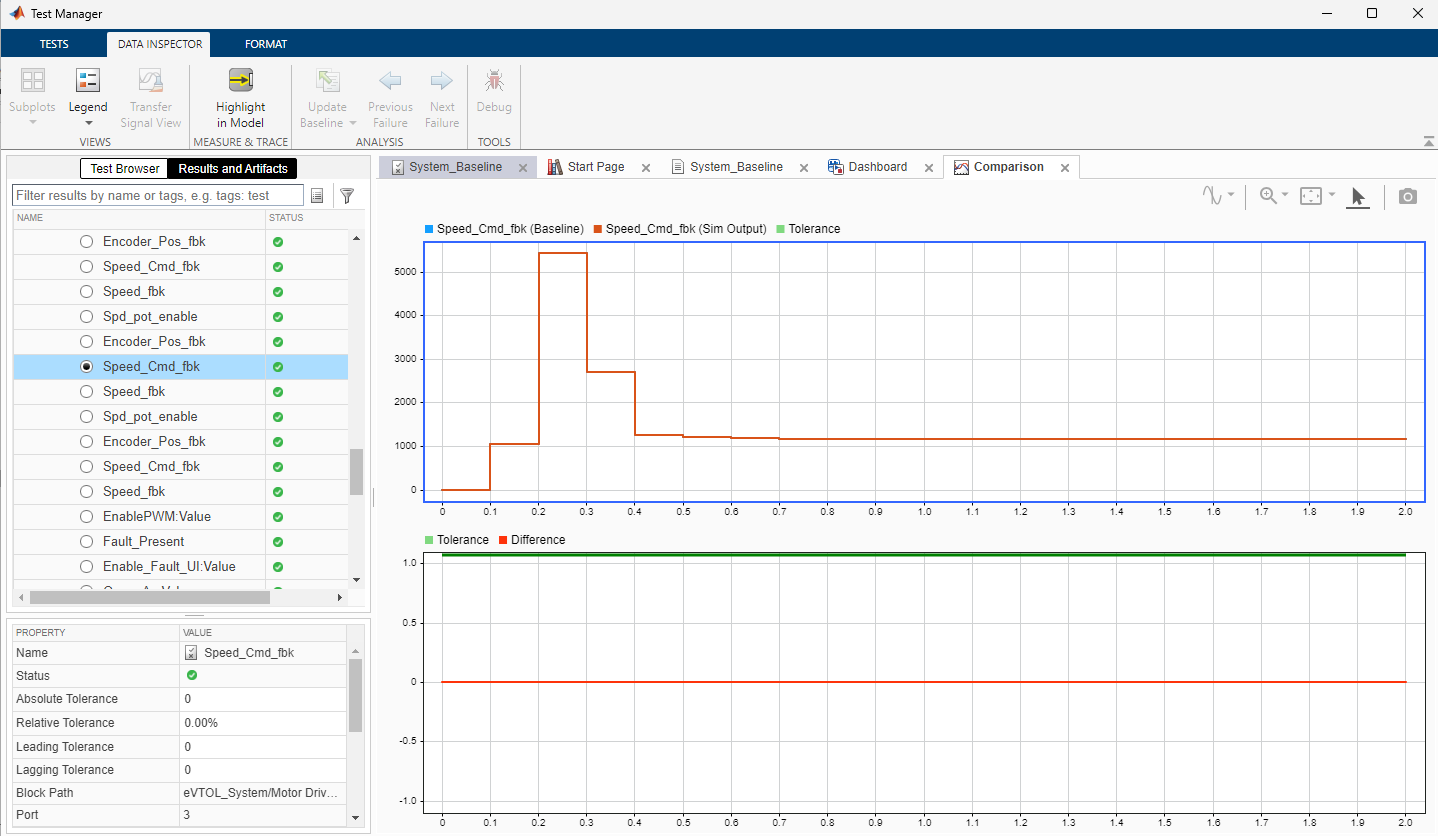

The tests also allow you to set a tolerance level and a delay value, both of which can be adjusted before each test based on the accepted error margin.

#### D2. Component-level Tests - BMS

Similar to System tests, there are pre-defined BMS tests as well that compare the test results to a baseline data.

Use the following commands to open Simulink® Test™ Manager with a predefined HIL baseline test scenario and compare the test results as done in the previous section.

sltestmgr
sltest.testmanager.load('eVTOL_BMS_Test.mldatx')
sltest.testmanager.run

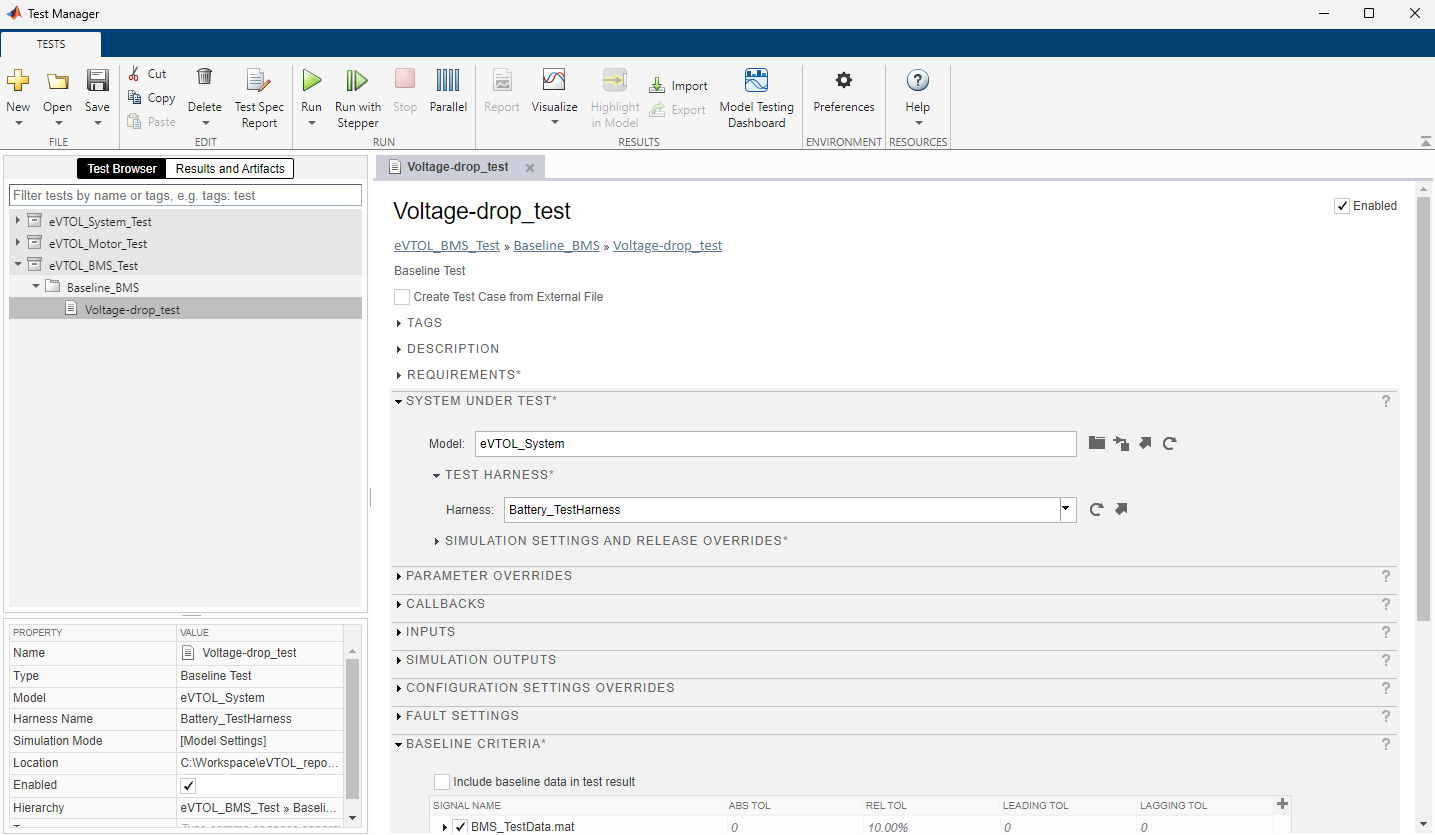

In this test, the battery system is detached from the rest of the system and a harness is created, as seen in the image below. A pre-defined signal (the required pack current, in this case) is given as an input to the harness to find voltage drops with different discharge current values.

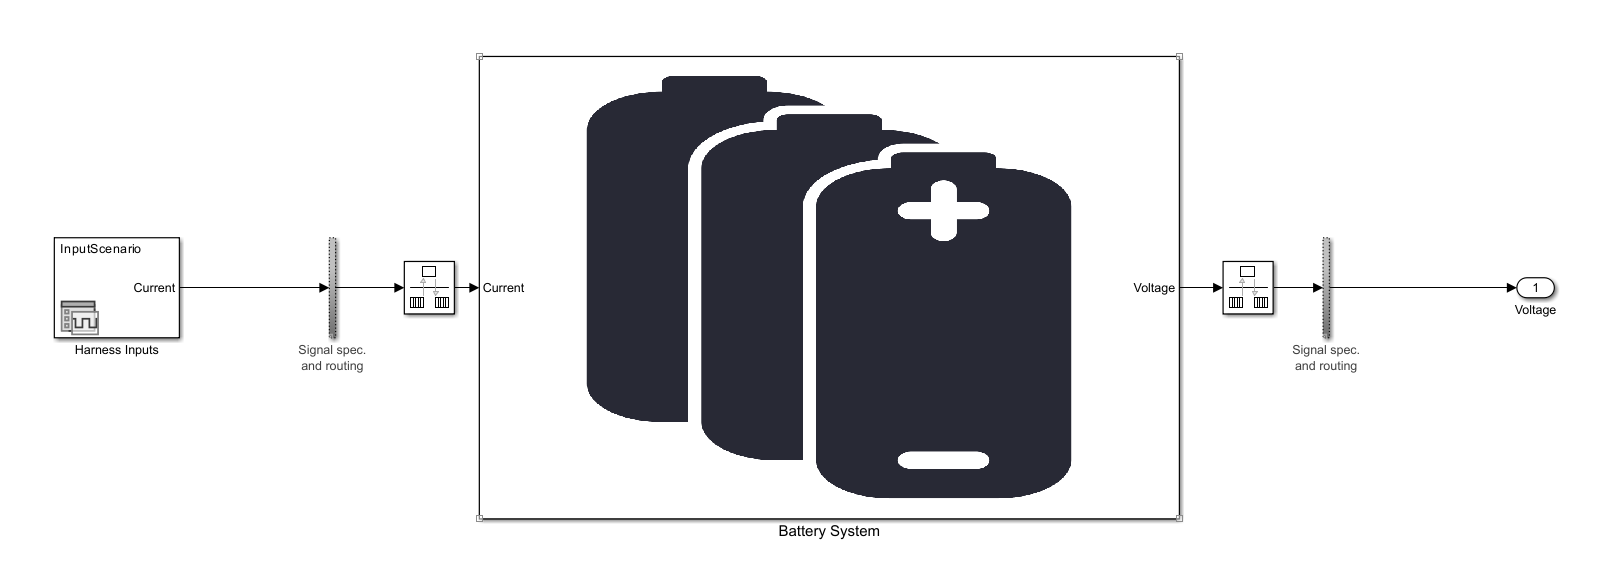

It can be observed that the pack currents are increasing as intended to.

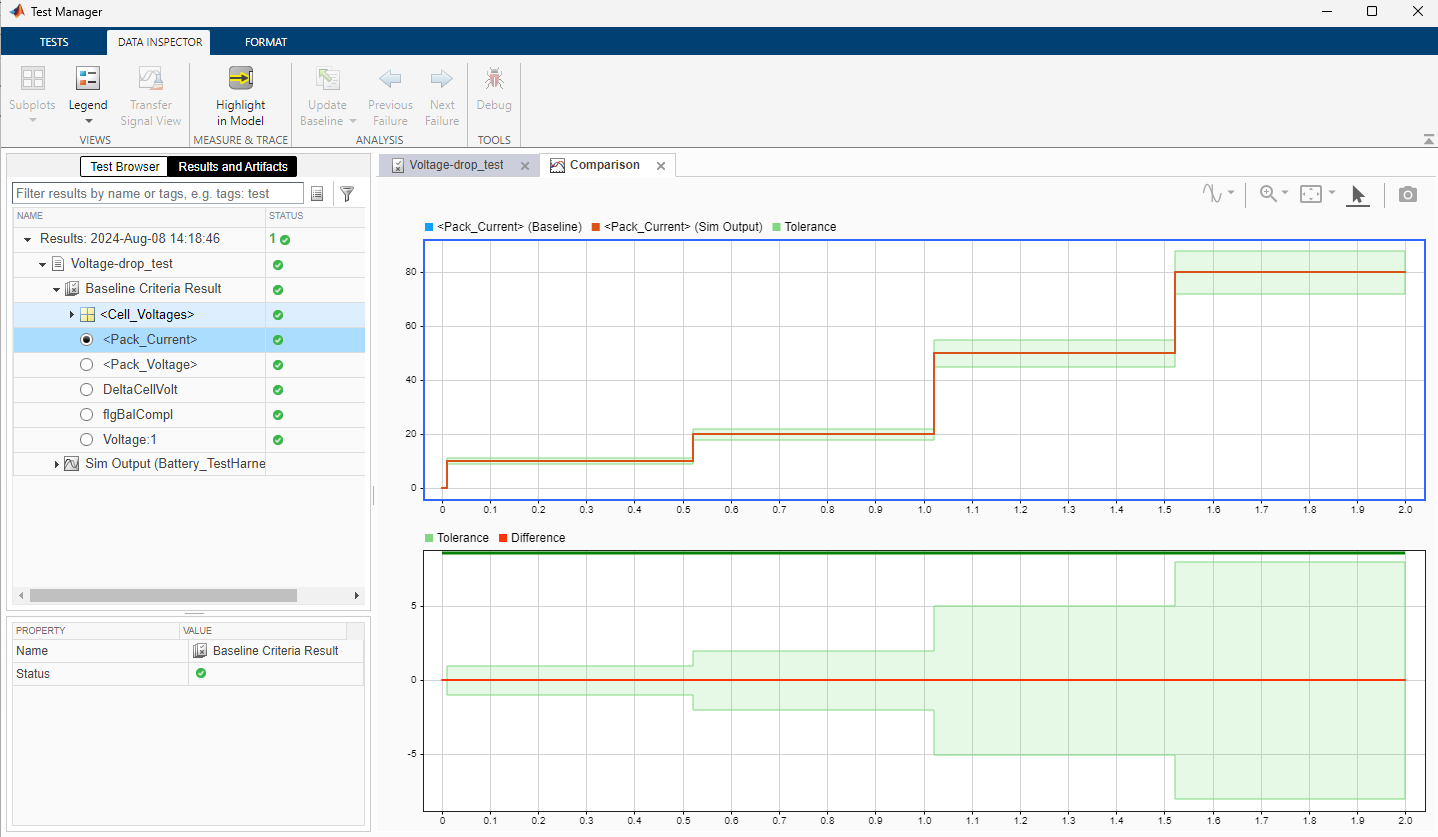

And the voltage drops is within the required limit as stated in the requirements. This passes the test as well as the requirement linked to this test. Requirements can be linked to each test case using [Requirement editor](https://ch.mathworks.com/help/slrequirements/ref/requirementseditor-app.html) which is a part of the [Requirements Toolbox™](https://ch.mathworks.com/products/requirements-toolbox.html). Refer to 'Requirements-based Testing' section for more details.

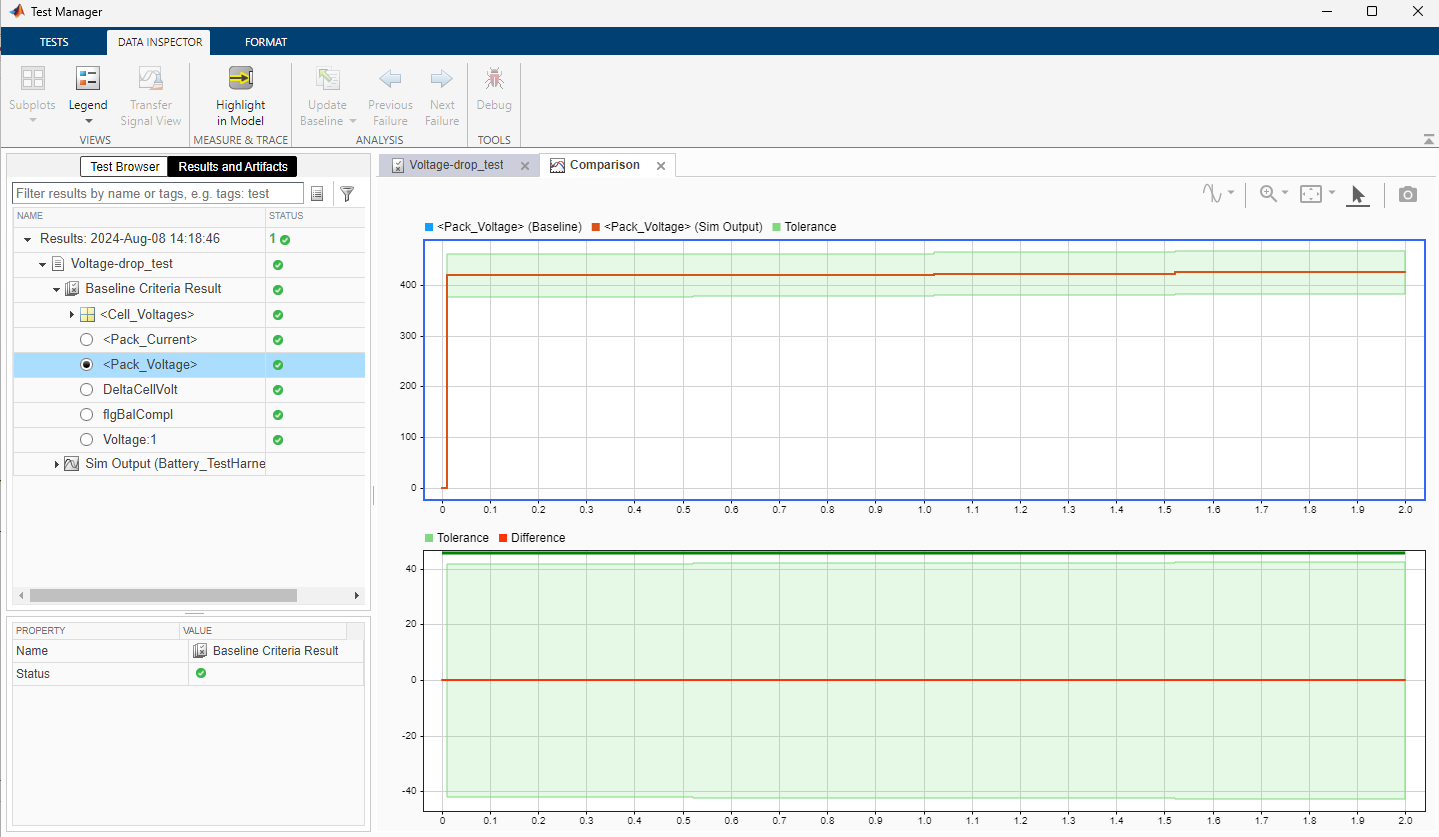

#### D3. Component-level Tests - MCU 

Similar to the previously defined tests, the MCU can also be tested using Simulink® Test™ Manager. Use the following commands to open Simulink® Test™ Manager with a predefined HIL baseline test scenario and compare the results as demonstrated in the previous section.

sltestmgr
sltest.testmanager.load('eVTOL_Motor_Test.mldatx')
sltest.testmanager.run

The image below displays the test harness used to test CAN signals from the MCU. Any component of the system can be tested in a similar manner, as demonstrated in this and the previous examples.

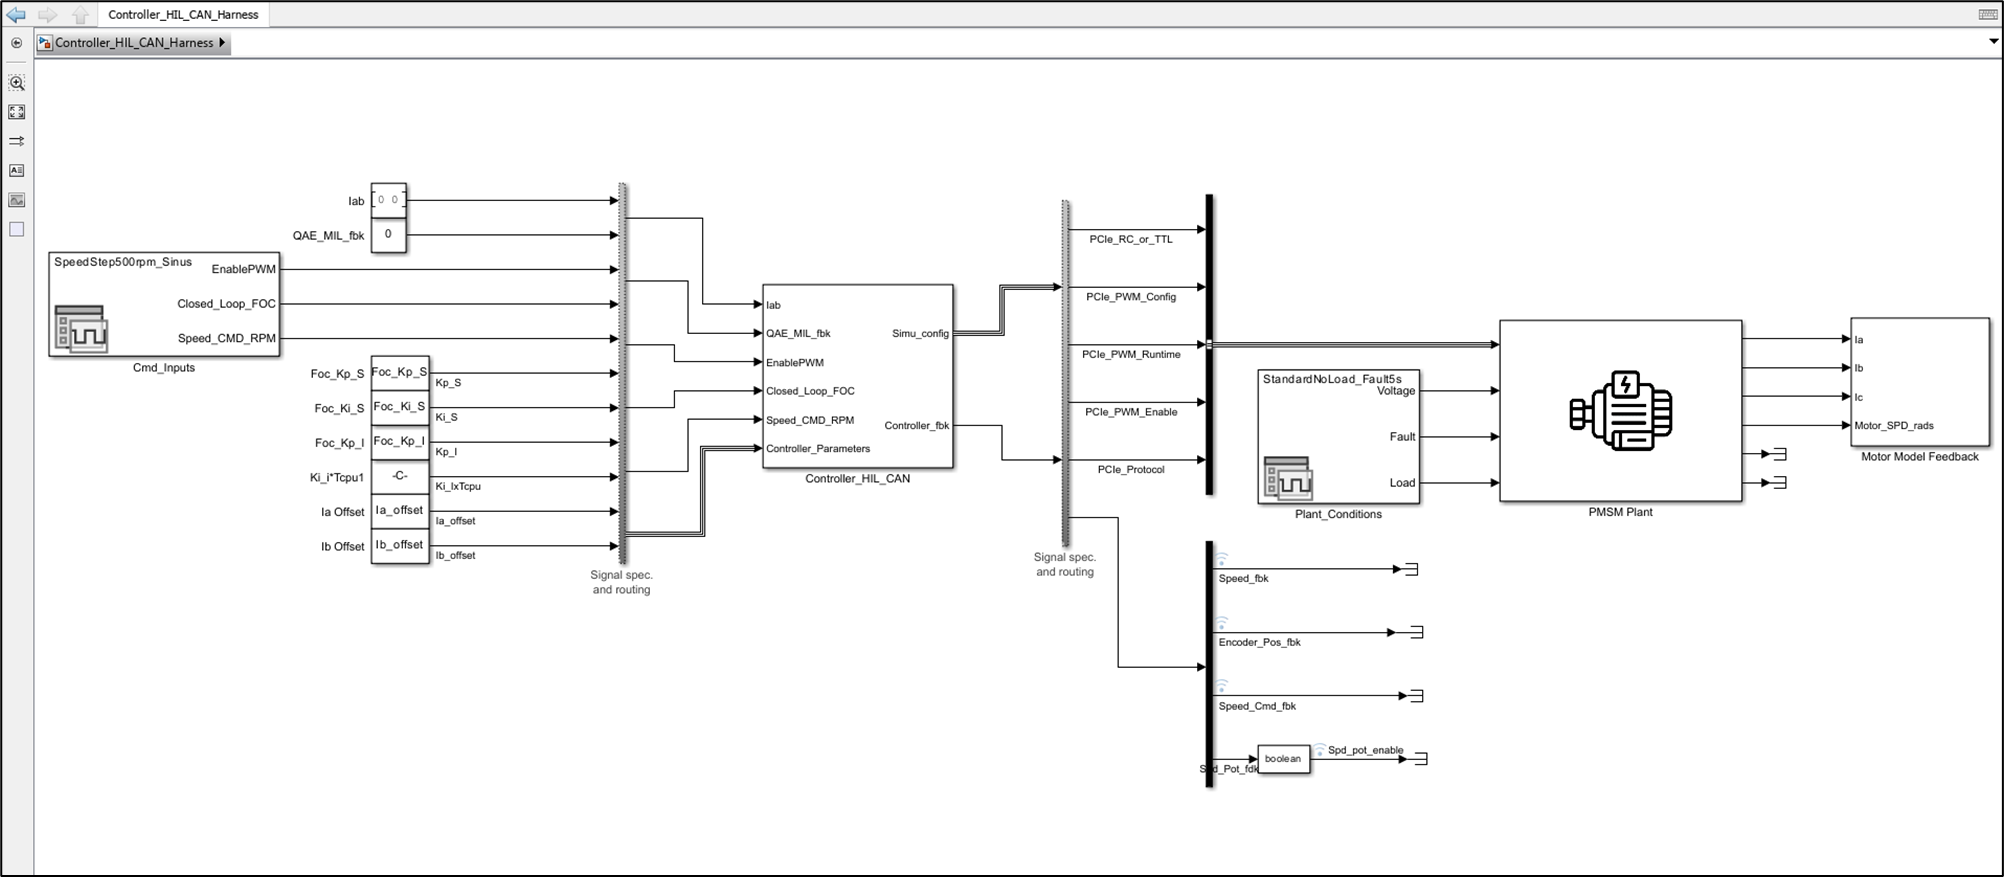

#### D4. Requirements-based Testing

This example highlights some of the requirements defined for the application. In the image below, the "Implemented" and "Verified" columns indicate whether the requirements have been implemented and if the corresponding tests have passed. Each requirement is also linked to the subsystem or block in the model where the feature is implemented. The requirements file, named *eVTOL_Requirements.slreqx*, is saved in the Tests folder.

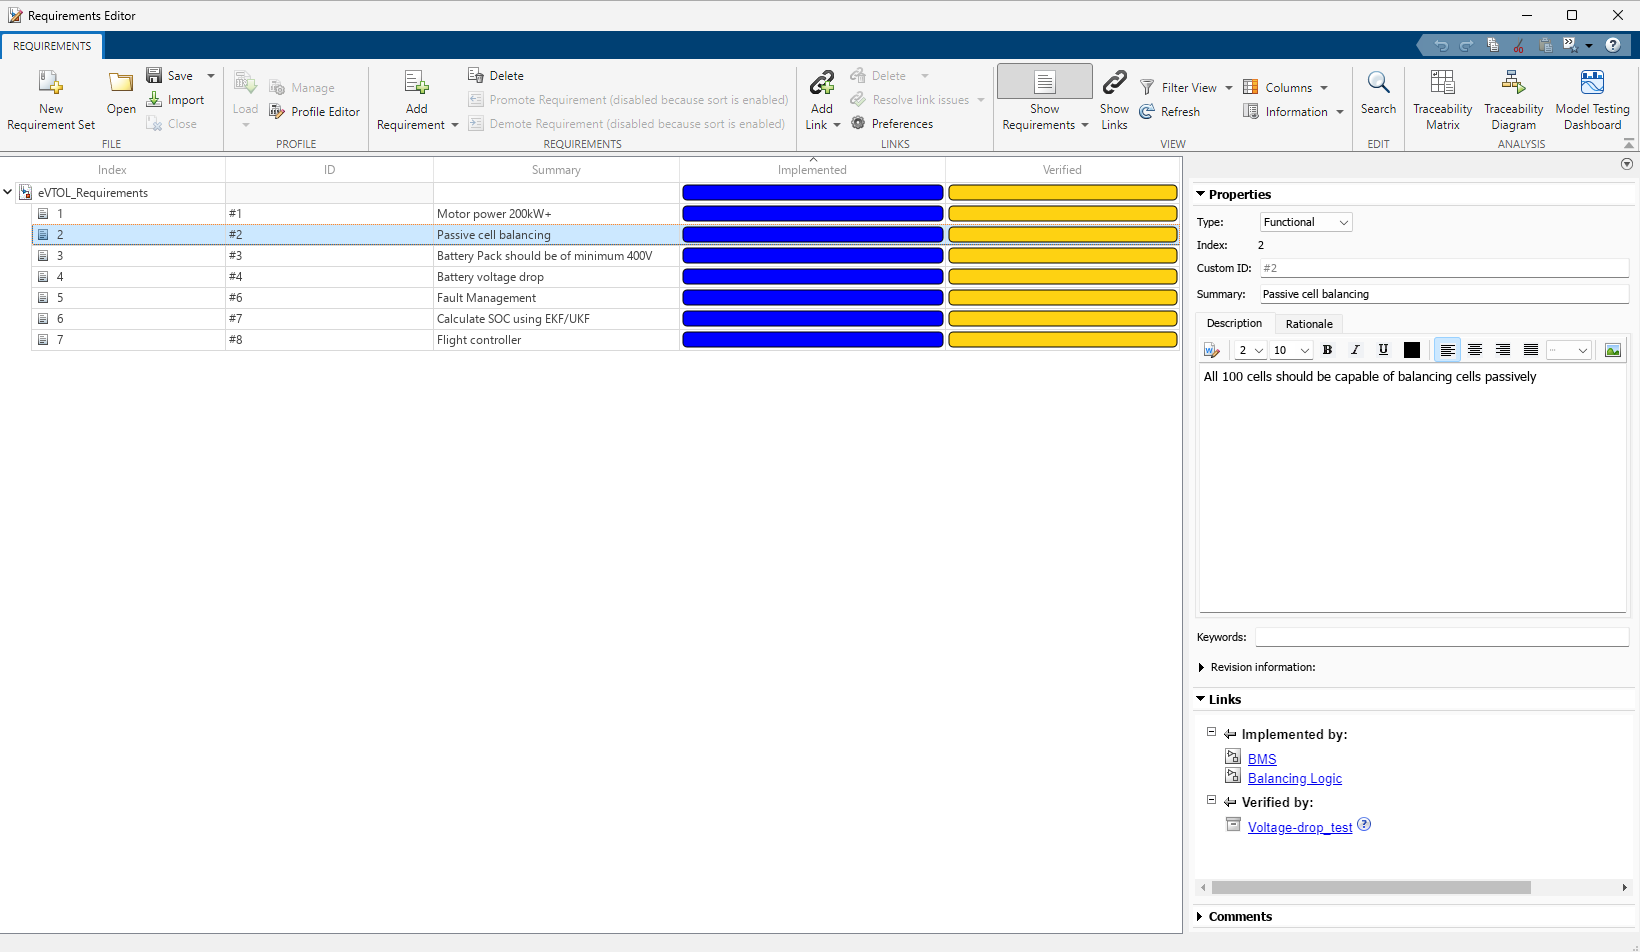

Each requirement in the Requirements Editor is linked to a test in Simulink® Test™ Manager. In the image above, while all requirements are implemented, they are not yet verified. Once a test is run and passes, the corresponding requirement will be marked as verified, as shown in the image below, where a successful system test confirms that the flight controller has been implemented and verified.

When a test passes, the Requirements Editor updates the requirement status to green, indicating it has been implemented and verified. Similarly, if all tests pass, all requirements in the editor will turn green. To verify this, run the tests defined in *eVTOL_System_Test.mldatx*, *eVTOL_BMS_Test.mldatx*, and *eVTOL_Motor_Test.mldatx*, then check the Requirements Editor for updates.

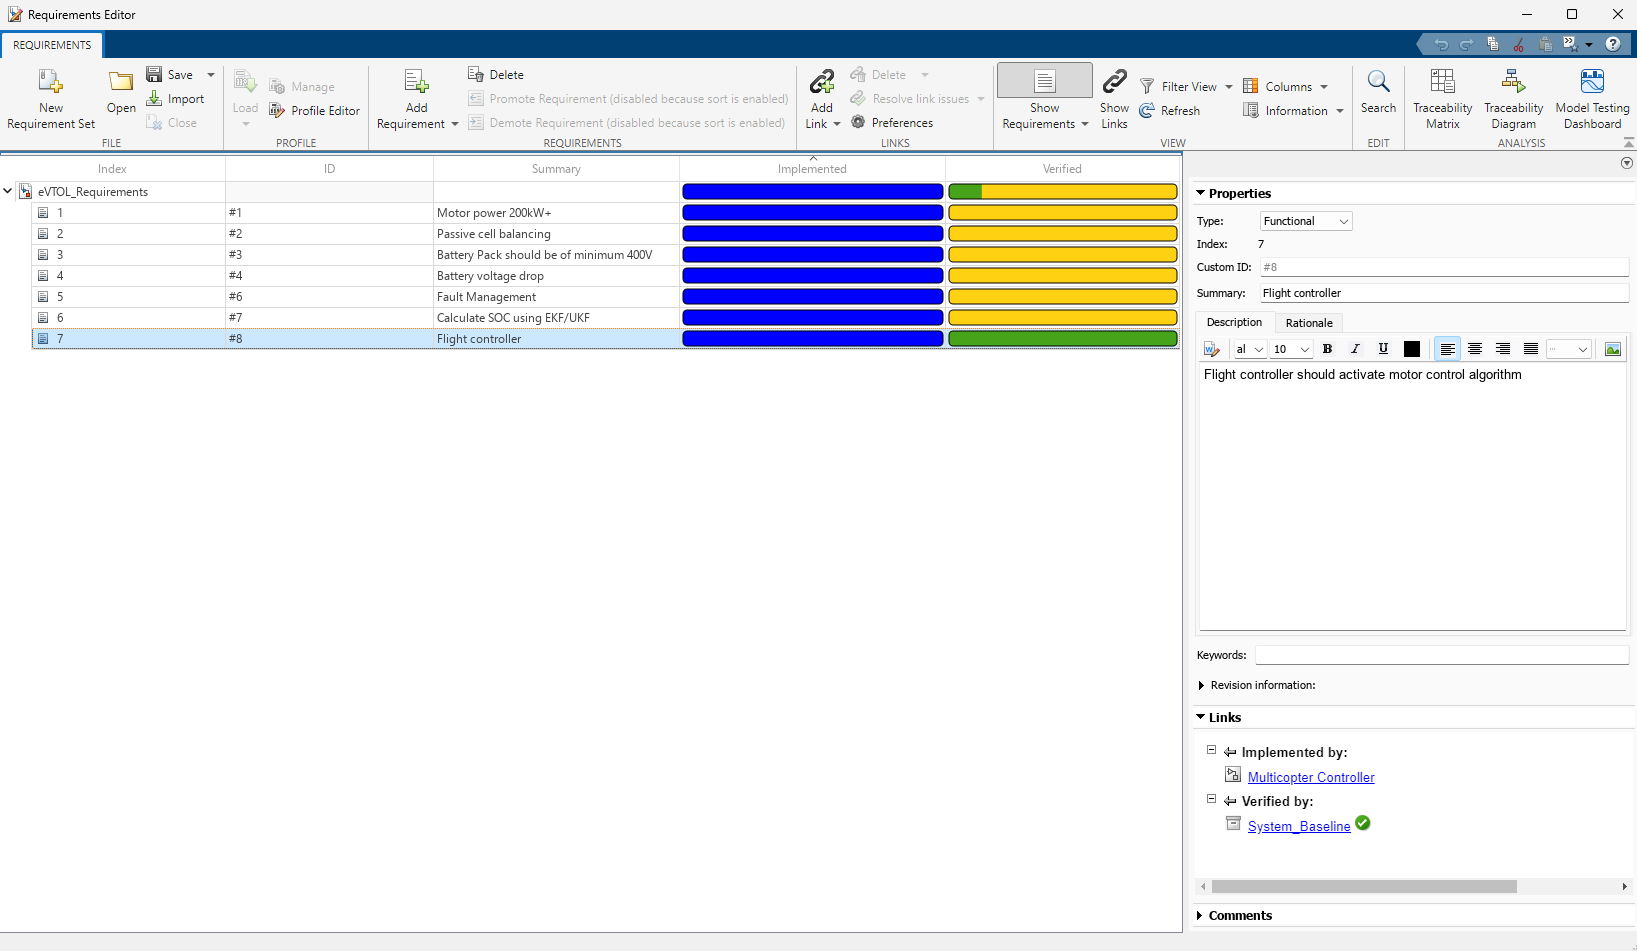

#### D5. Automate Testing with Continuous Integration

You can use Continuous Integration (CI) workflows to accelerate development and testing of your eVTOL Powertrain controllers. This enables your team to adopt and adhere to [agile development practices](https://ch.mathworks.com/solutions/agile-development.html) throughout your development lifecycle all without losing the benefits of HIL simulation and testing.

You can run MATLAB®, Simulink®, Simulink® Real-Time™ and Simulink® Test™ on a on-premises HIL CI server and benefit from off-the-shelf integration with mainstay CI platforms like Jenkins, Gitlab or Azure Devops. And all can be orchestrated to work with hardware and complement your HIL testing workflows.

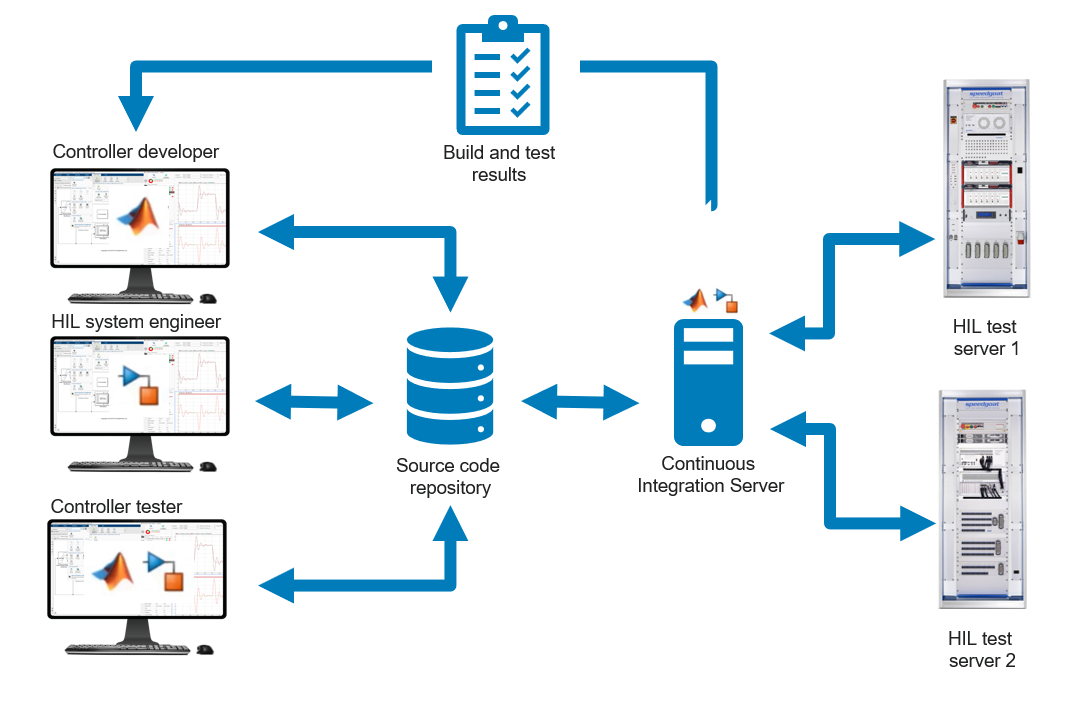

The following command executes an example CI pipeline on that carries out the following actions:

run CI_HIL_test.m

The following steps are take place when the above command is executed.

- Opens the eVTOL-Powertrain-HIL Simulink® project.

- Loads the test file 'eVTOL_System_Test.mldatx' in the Simulink® Test™ Manager.

- Runs Simulink® Test™ test-cases defined within the file.

- Generates a .zip file with the test results.

Next, you have the option to integrate this and other CI pipelines into a CI platform, allowing for the complete automation of tasks such as downloading the Simulink® project, executing HIL test cases, and automatically sending notifications in the event of a testing pipeline failure. 

For a comprehensive demonstration of CI within the context of controller HIL testing, we recommend watching the following webinar: [Automated and Continuous Hardware-in-the-Loop Testing](https://www.speedgoat.com/knowledge-center/webinars/automated-and-continuous-hardware-in-the-loop-testing)

## Release Notes

open README.md